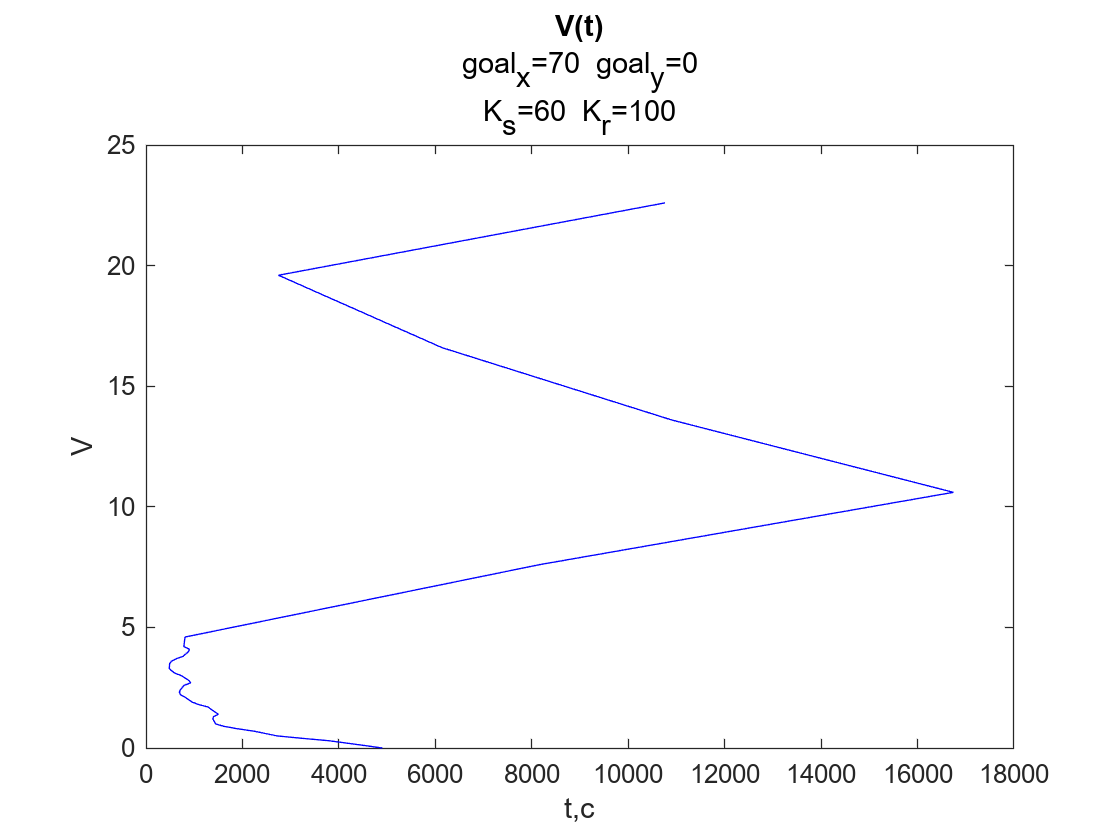

ke = 0.4987;
km = ke; 
R =  8.8696;
L = 0.0047;
J = 0.0023;
r=0.028;
B=0.21;

data=readmatrix('lab4_data\non_linear_(70 0)_(60 100).txt');
K_s=60;
K_r=100;

goal_x=70;
goal_y=0;

V=data(:,4);
t=data(:,5);

h1=strcat('goal_x=',string(goal_x),'  goal_y=', string(goal_y));
h2 = strcat('K_s=',string(K_s),'  K_r=', string(K_r));

plot(V,t,'b')

title('V(t)',{h1,h2})
xlabel('t,c')
ylabel('V')
path = 'D:\VPD_lab_4\Plot';

Name = 'V(t)_non_linear_(70 0)_(60 100)';

fullpath = fullfile(path, Name);

saveas(gcf, fullpath, 'png');